%reading in Data
BaseballData = readtable("C:\\Users\\Andrew Moss\\Documents\\Rangers pitch data.csv");
%selecting the columns I'm going to use as predictors in my model
Predictors = BaseballData(1:end,6:end);

%two of the columns that were numerical inexplicably came in as string.
%Here's casting them
Predictors.effective_speed = str2double(Predictors.effective_speed);
Predictors.release_spin_rate = str2double(Predictors.release_spin_rate);




%%Creating matrices with the X's for different Y's: predicting the pitcher
%%name and the pitch type and handedness per the project
Pitch_Hand = BaseballData(1:end,3);
Pitch_HandTab = table2cell(Pitch_Hand);
Pitch_HandTab = string(Pitch_HandTab)

Pitch_HandTab = 15836×1 string array
    "FF-R"
    "FF-R"
    "FF-R"
    "FF-R"
    "FF-R"
    "CH-R"
    "CH-R"
    "FF-R"
    "FF-R"
    "FF-R"
    "CH-R"
    "FF-R"
    "FF-R"
    "CH-R"
    "CH-R"
    "CH-R"
    "FF-R"
    "FF-R"
    "CU-R"
    "FF-R"
    "CH-R"
    "FF-R"
    "FT-R"
    "CU-R"
    "FF-R"
    "FT-R"
    "CU-R"
    "FT-R"
    "FF-R"
    "FT-R"



Pitcher_Name = BaseballData(1:end,4);

Predictors_Hand = horzcat(Pitch_Hand,Predictors);
Predictors_Player = horzcat(Pitcher_Name,Predictors);


%fitting tree
BaseballTree = fitctree(Predictors_Hand, "Pitch_hand","CrossVal","on","KFold",10);
BaseballTreeView = fitctree(Predictors_Hand,"Pitch_hand")

BaseballTreeView =   ClassificationTree
           PredictorNames: {'release_pos_x'  'release_pos_z'  'pfx_x'  'pfx_z'  'plate_x'  'plate_z'  'vx0'  'vy0'  'vz0'  'ax'  'ay'  'az'  'sz_top'  'sz_bot'  'effective_speed'  'release_spin_rate'  'release_extension'  'release_pos_y'}
             ResponseName: 'Pitch_hand'
    CategoricalPredictors: []
               ClassNames: {'CH-L'  'CH-R'  'CU-L'  'CU-R'  'FF-L'  'FF-R'  'FT-L'  'FT-R'}
           ScoreTransform: 'none'
          NumObservations: 15836


  Properties, Methods


%%viewing tree
view(BaseballTreeView,'Mode','graph')

%% getting the accuracies for the tree
TreePreds = BaseballTree.kfoldPredict;

TreePreds = string(TreePreds);
TreeAcc = getAcc(TreePreds,Pitch_HandTab)

TreeAcc = 0.9744

confusionchart(Pitch_HandTab,TreePreds,"Title","Confusion Matrix for Decision Tree Classifier")

ans =   ConfusionMatrixChart (Confusion Matrix for Decision Tree Classifier) with properties:

    NormalizedValues: [8×8 double]
         ClassLabels: [8×1 string]

  Show all properties


%% fitting the KNN model
BaseballKNN = fitcknn(Predictors_Hand,"Pitch_hand","Distance","cosine","BreakTies","nearest","CrossVal","on","KFold",10,"NSMethod","exhaustive");

%% getting the preds, k number, accuracy, and confusion matrix for KNN
KNNPreds = BaseballKNN.kfoldPredict;
KNNPreds = string(KNNPreds);
KNNAcc = getAcc(KNNPreds,Pitch_HandTab)

KNNAcc = 0.9550

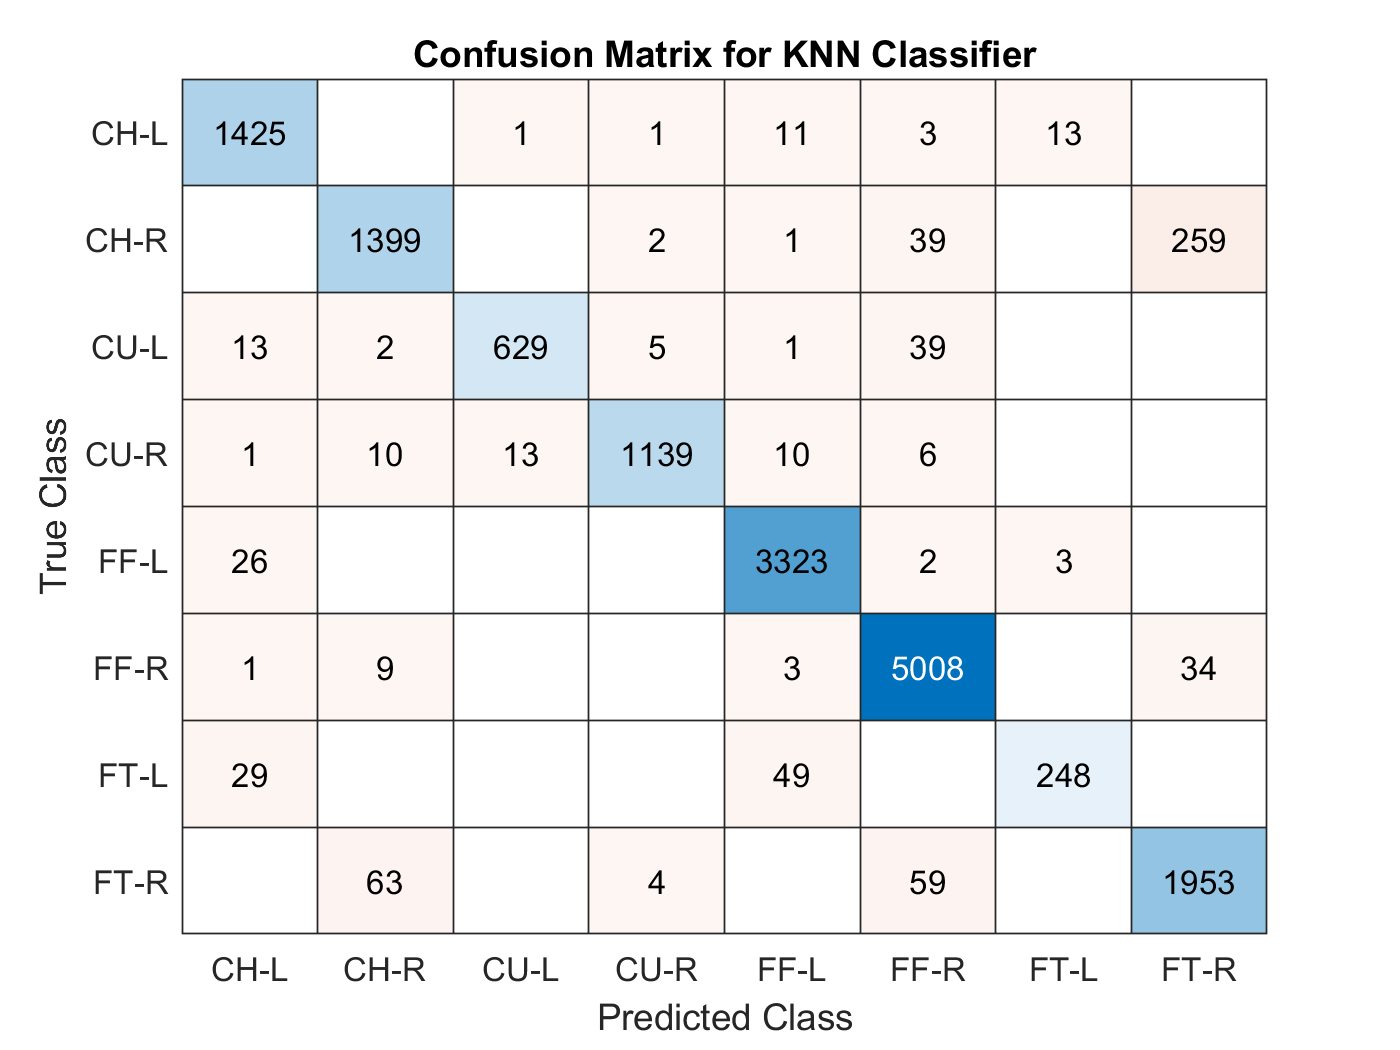

ans =   ConfusionMatrixChart (Confusion Matrix for KNN Classifier) with properties:

    NormalizedValues: [8×8 double]
         ClassLabels: [8×1 string]

  Show all properties


confusionchart(Pitch_HandTab,KNNPreds,"Title","Confusion Matrix for KNN Classifier")

%% fitting the Naive Bayes model and getting the preds, accuracy, and confusion matrix
BaseballNB = fitcnb(Predictors_Hand,"Pitch_hand","CrossVal","on","KFold",10);
NBPreds = BaseballNB.kfoldPredict;
NBPreds = string(NBPreds);
NBAcc = getAcc(NBPreds,Pitch_HandTab)

NBAcc = 0.9666

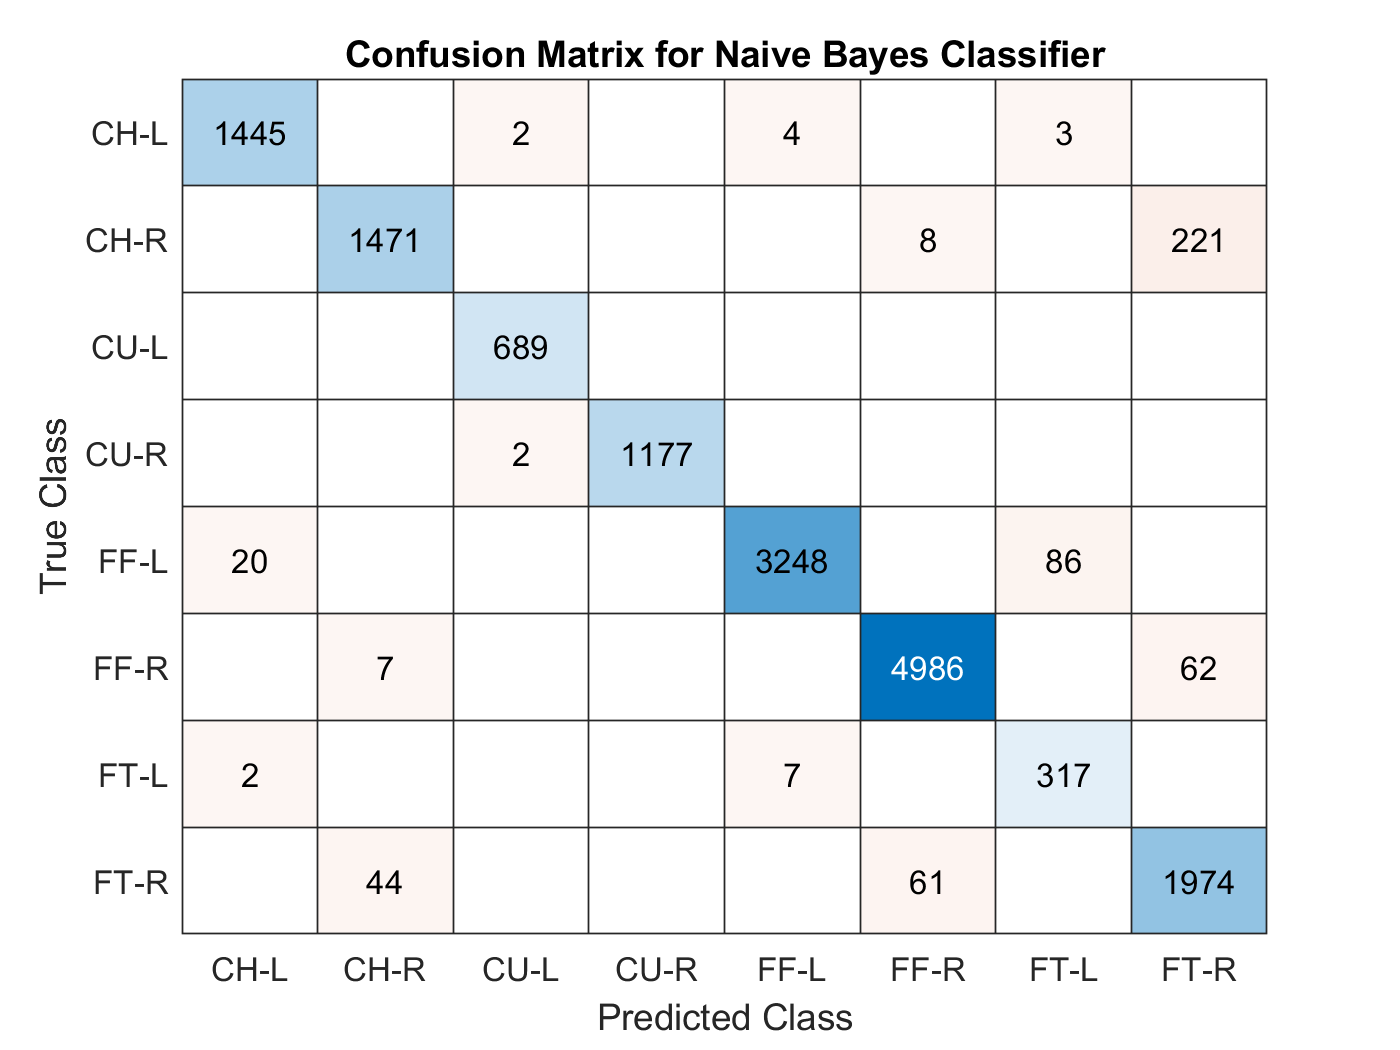

ans =   ConfusionMatrixChart (Confusion Matrix for Naive Bayes Classifier) with properties:

    NormalizedValues: [8×8 double]
         ClassLabels: [8×1 string]

  Show all properties



confusionchart(Pitch_HandTab,NBPreds,"Title","Confusion Matrix for Naive Bayes Classifier")

Accuracy function

function Accuracy = getAcc(x,y)
    Accuracy = 0;
    if size(x)~= size(y)
        Accuracy = -1;
    else
        for i = 1:size(x)
            if x(i) == y(i)
                Accuracy = Accuracy+1;
            end
        end
        Accuracy = Accuracy/i;
    end
end